Here is an example how to use `mexgdal` with Mapping Toolbox to show a HFA (Erdas Imageine) format file.

Read bands. This is a single-band image. Simply display it as a image

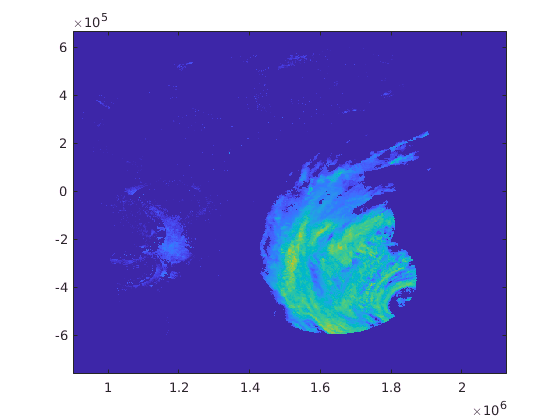

f = 'data/20030918-093102.img';
[x, y, z] = readgdalsimple(f);
figure;
image(x, y, z)
set(gca, 'YDir', 'Normal')

We'd like to them actually plot on a map. First let us check the spatial reference, read the WKT into mstruct using `prjparse`

m = gdaldump(f);
projection = prjparse(m.ProjectionRef);

Searching for North_America_Lambert_Conformal_Conic projection...
North America Lambert Conformal Conic projection found!
creating projection struct
geoid set
origin set
falseeasting set
falsenorthing set


projection.mapprojection

ans = 'lambertstd'

OK. It is a Lambert Conformal Conic.  To work with Mapping Toolbox, we need inverse project x/y to lat/lon

X = linspace(x(1), x(2), m.RasterXSize);
Y = linspace(y(1), y(2), m.RasterYSize);
[x1, y1] = meshgrid(X,Y);
[lat,lon] = minvtran(projection, x1, y1);

Then we can plot them

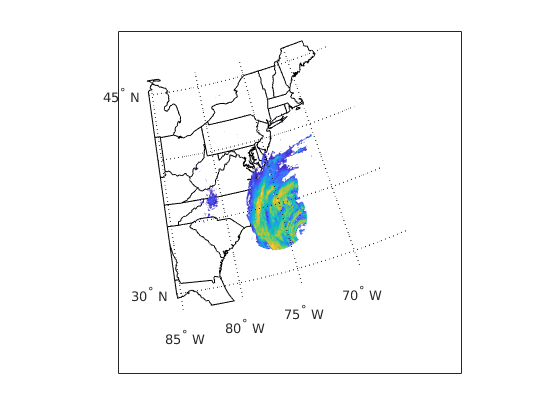

figure;
axesm(projection, ...
    'MapLatLimit', [min(lat(:)) max(lat(:))], ...
    'MapLonLimit', [min(lon(:)) max(lon(:))], ...
    'Grid', 'on', ...
    'PLineLocation', 5, ...
    'MLineLocation', 5, ...
    'ParallelLabel', 'on', ...
    'MeridianLabel', 'on', 'MLabelLocation', 5);
states = shaperead('usastatelo', 'UseGeoCoords', true);
geoshow(states,'FaceColor',[1,1,1]);
z(z<10) = nan;
pcolorm(lat, lon, z);